# Bike Data Analysis

Add the path to your data or include it in the file name below 

addpath('StatisticsPrimerDataFiles/')

Clear other variables from your workspace and load the bike data as a table from a csv file

filename = 'bikedata.csv'; % Include the path to the file or use addpath
% Detect the variable types and change them to what you want (mostly to get categorical variables instead of cells of strings)
opts = detectImportOptions(filename);
opts.VariableTypes = {'categorical','categorical','double','categorical','double','double','double','categorical','datetime','double'};

bike = readtable(filename,opts); %actually read the data
% Get some details about the data
bike.Properties.VariableNames

ans = 1×10 cell array
    'vehicle'    'colour'    'passingDistance'    'street'    'helmet'    'kerb'    'bikelane'    'City'    'dateandtime'    'perceivedDistance'


class(bike.vehicle)

ans = 'categorical'

class(bike.passingDistance)

ans = 'double'

summary(bike)


Variables:

    vehicle: 2355×1 categorical

        Values:

            HGV               82     
            LGV/minibus      293     
            PTW               34     
            SUV/pickup       143     
            bus               46     
            ordinary car    1708     
            taxi              49     

    colour: 2355×1 categorical

        Values:

            black          262     
            blue           636     
            green          149     
            other           52     
            red            378     
            silver/grey    531     
            unknown         14     
            white          333     

    passingDistance: 2355×1 double

        Values:

            Min       0.394            
            Median    1.529            
            Max       3.787            

    street: 2355×1 categorical

        Values:

            main road (regular)          

## Begin your exploratory analysis here.  Be sure to use the text/comment options to explain what you are doing (and why).

# Characterize overall data

Ultimately, the goal of this research is to understand how various factors impact the passing distance and percieved passing distance between the car and the bike.

We will start by collecting some agregate statistics about those two parameters, so that we can compare subgroups of the data to these overall statistics.

One unconventional statistic I have included in this analysis is the fraction of passing events within 1m of the cyclist, in an attempt to measure the fraction of events that are "dangerously close".

Count:


ans = 2355

Quantiles:


ans =     1.3030    1.5290    1.7913


Mean:


ans = 1.5639

Standard Deviation:


ans = 0.3835

Fraction <=1m:


ans = 0.0463

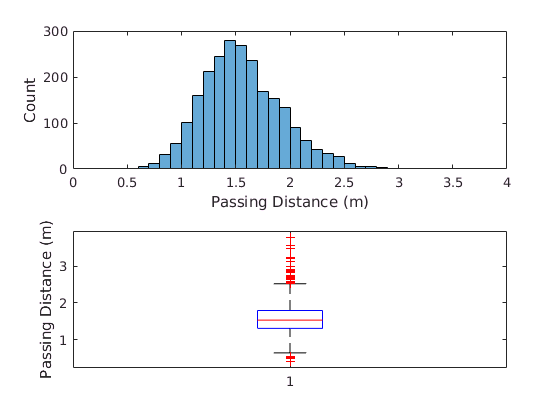

bikesummary(bike.passingDistance, 'Passing Distance')

Count:


ans = 2355

Quantiles:


ans =     1.2434    1.5208    1.8488


Mean:


ans = 1.5579

Standard Deviation:


ans = 0.4570

Fraction <=1m:


ans = 0.1134

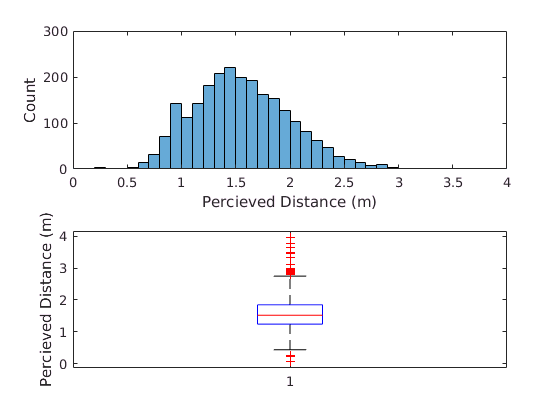

bikesummary(bike.perceivedDistance, 'Percieved Distance')

In addition to providing a baseline for later comparisions, these figures indicate that there are a few differences between the two measurements. Although both have nearly the same mean, the percieved distance has more variation than the measured distance, and (0.45 > 0.38), and has more than twice as many "dangerous passing" events (11% vs 4.6%). The correlation between the two is high, but not perfect, implying that there is some useful data being captured by each.

corr(bike.passingDistance, bike.perceivedDistance)

ans = 0.8627

Analysis code used to generate these results can be found at the bottom of the file.

# Compare based on helmet status

Now, we will compare the statistics generated above to filtered subsets of the data based on whether the rider was wearing a helmet.

---------------------------------


Count:


Helmet off: 1206


Helmet on: 1149


Mean:


Helmet off: 1.6054


Helmet on: 1.5203


Std. Dev:


Helmet off: 0.4053


Helmet on: 0.35407


Fraction <=1m:


Helmet off: 0.04063


Helmet on: 0.052219


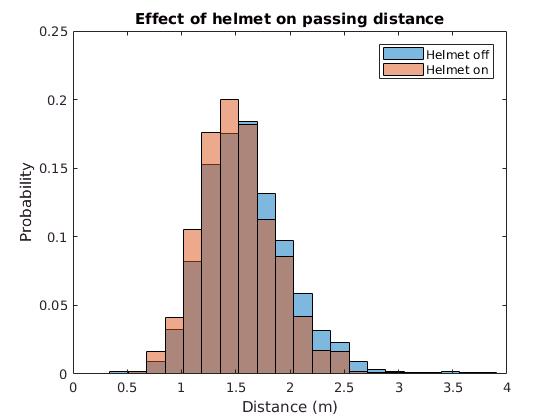

bikecompare(bike.passingDistance, ...
    bike.helmet==0, 'Helmet off', ...
    bike.helmet==1, 'Helmet on', ...
    "Effect of helmet on passing distance")

We can see that when the rider is wearing a helmet, cars pass on average 8cm closer to the cyclist, and significantly more cars pass within 1m of the cyclist (5% vs 4%). To analyze this connection farther, we look at the correlation of these two parameters.

corr(bike.passingDistance, bike.helmet)

ans = -0.1110

This negative correlation indicates that wearing a helmet decreases the expected passing distance.

## Repeat tests using Perceived Distance

---------------------------------


Count:


Helmet off: 1206


Helmet on: 1149


Mean:


Helmet off: 1.6031


Helmet on: 1.5104


Std. Dev:


Helmet off: 0.48189


Helmet on: 0.42443


Fraction <=1m:


Helmet off: 0.10199


Helmet on: 0.12533


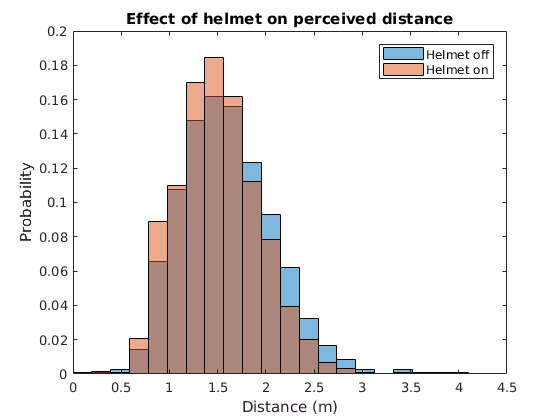

bikecompare(bike.perceivedDistance, ...
    bike.helmet==0, 'Helmet off', ...
    bike.helmet==1, 'Helmet on', ...
    "Effect of helmet on perceived distance")


corr(bike.passingDistance, bike.helmet)

ans = -0.1110

These results look much the same as the data for passing distance.

In conclusion, cars appear to pass significantly closer to cyclists who are wearing a helmet, which is associated with a 20% increase in the number of "dangerous" passing incidents.

# Compare based on vehicle type

For each vehicle type, we will compare the perceived distance from that type with the passing distance for all other vehicle types.

## Bus

---------------------------------


Count:


Bus: 46


Other vehicles: 2309


Mean:


Bus: 1.3297


Other vehicles: 1.5686


Std. Dev:


Bus: 0.29784


Other vehicles: 0.38357


Fraction <=1m:


Bus: 0.086957


Other vehicles: 0.045474


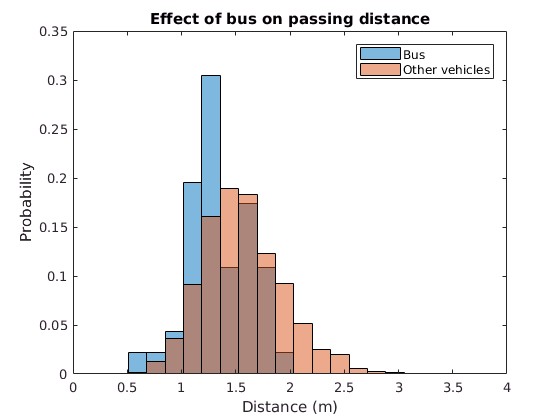

bikecompare(bike.passingDistance, ...
    bike.vehicle=='bus', 'Bus', ...
    bike.vehicle~='bus', 'Other vehicles', ...
    "Effect of bus on passing distance")

Busses seem to pass extremely close to cyclists compared to other vehicles, almost 30cm closer on average. In addition, 28% of busses pass within the percieved danger zone, compared to other vehicles. The significance of these results may be called into question by the fact that only 46 busses are present in the data set.

## SUV/pickup

---------------------------------


Count:


SUV/Pickup: 143


Other vehicles: 2212


Mean:


SUV/Pickup: 1.5784


Other vehicles: 1.563


Std. Dev:


SUV/Pickup: 0.37931


Other vehicles: 0.38379


Fraction <=1m:


SUV/Pickup: 0.062937


Other vehicles: 0.045208


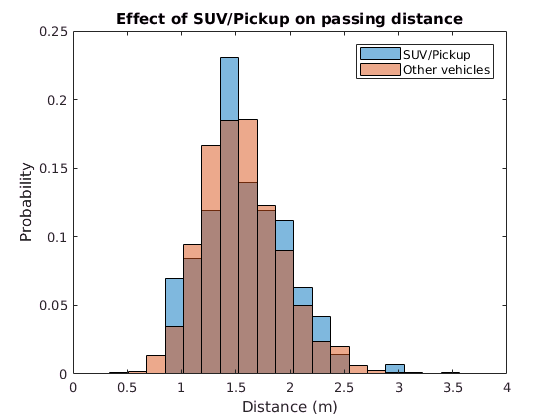

bikecompare(bike.passingDistance, ...
    bike.vehicle=='SUV/pickup', 'SUV/Pickup', ...
    bike.vehicle~='SUV/pickup', 'Other vehicles', ...
    "Effect of SUV/Pickup on passing distance")

In contrast, while SUV/pickup encounters do seem to have a different distribution of distances, they do not pass closer on average than other vehicles, nor do they pass dangerously close significantly more often then other vehicles.

## LGV/minibus

---------------------------------


Count:


LGV/minibus: 293


Other vehicles: 2062


Mean:


LGV/minibus: 1.5182


Other vehicles: 1.5704


Std. Dev:


LGV/minibus: 0.35156


Other vehicles: 0.38742


Fraction <=1m:


LGV/minibus: 0.051195


Other vehicles: 0.045587


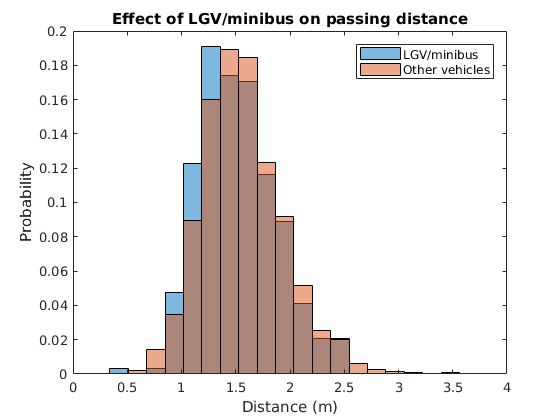

bikecompare(bike.passingDistance, ...
    bike.vehicle=='LGV/minibus', 'LGV/minibus', ...
    bike.vehicle~='LGV/minibus', 'Other vehicles', ...
    "Effect of LGV/minibus on passing distance")

# Compare based on City

---------------------------------


Count:


Bristol: 450


Salisbury: 1905


Mean:


Bristol: 1.5411


Salisbury: 1.5693


Std. Dev:


Bristol: 0.40685


Salisbury: 0.37763


Fraction <=1m:


Bristol: 0.066667


Salisbury: 0.04147


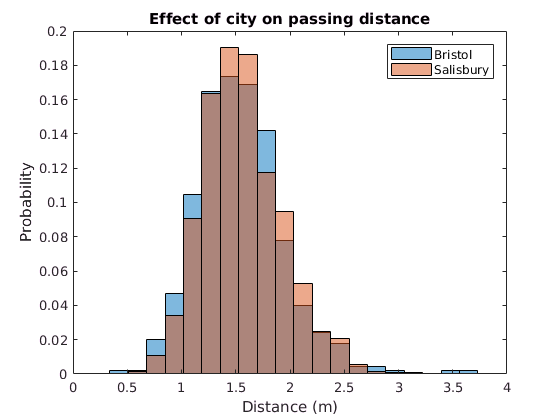

bikecompare(bike.passingDistance, ...
    bike.City=='Bristol', 'Bristol', ...
    bike.City=='Salisbury', 'Salisbury', ...
    "Effect of city on passing distance")

---------------------------------


Count:


Bristol: 450


Salisbury: 1905


Mean:


Bristol: 1.5261


Salisbury: 1.5654


Std. Dev:


Bristol: 0.48888


Salisbury: 0.44898


Fraction <=1m:


Bristol: 0.14444


Salisbury: 0.10604


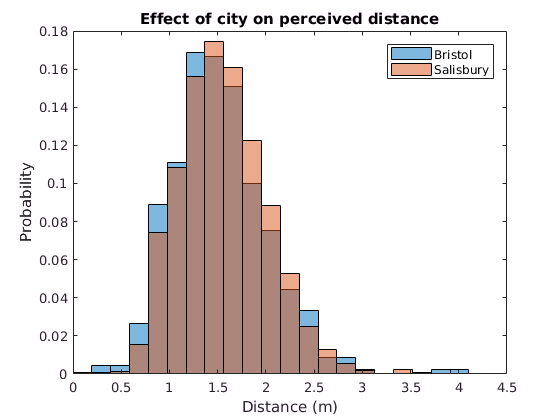


bikecompare(bike.perceivedDistance, ...
    bike.City=='Bristol', 'Bristol', ...
    bike.City=='Salisbury', 'Salisbury', ...
    "Effect of city on perceived distance")

The city seems to have a small effect on mean passing distance, but a larger effect on the percentage of "dangerous" encounters because the differences are concentrated at very short distances.

# Helper functions

function res=bikesummary(data, label)
figure
subplot(2,1,1)
histogram(data)
xlabel(strcat(label, ' (m)'))
ylabel('Count')

subplot(2,1,2)
boxplot(data)
ylabel(strcat(label, ' (m)'))

disp('Count:');
length(data)

disp('Quantiles:');
quantile(data,[.25 .50 .75])

disp('Mean:');
mean(data)

disp('Standard Deviation:');
std(data)

disp('Fraction <=1m:');
length(data(data<=1))/length(data)
end

function res=bikecompare(data, filter1, label1, filter2, label2, giventitle)
data1=data(filter1);
data2=data(filter2);

figure

% Overlaid histograms, building on stats notebook code
binwidth = (max(data)-min(data))/20; %Since multiple histograms, we want to align the bin widths
facealpha = 0.5; %transparency of fill colors: 0 to 1
h1 = histogram(data1,'BinWidth',binwidth,'FaceAlpha',facealpha);
h1.Normalization='probability';
hold on; %make them on the same plot
h2 = histogram(data2,'BinWidth',binwidth,'FaceAlpha',facealpha);
h2.Normalization='probability';
ylabel('Probability'); xlabel('Distance (m)'); title(giventitle);
legend({label1, label2});
hold off;

% Numeric data
    function dispNumbers(name, num1, num2)
        disp(' ');
        disp([name,':']);
        disp([label1, ': ', num2str(num1)]);
        disp([label2, ': ', num2str(num2)]);
    end

disp('---------------------------------')

dispNumbers('Count', length(data1), length(data2))
dispNumbers('Mean', mean(data1), mean(data2))
dispNumbers('Std. Dev', std(data1), std(data2))

dispNumbers('Fraction <=1m', ...
    length(data1(data1<=1))/length(data1), ...
    length(data2(data2<=1))/length(data2))
end